Reset
Models = "DirectedG" + ["0","1","2","4","5","6","7","8","9","10"] %["ATTM"];%    "CTRW"    "Fractal"    "Scaled"];% + "05";

Models = 1×10 string array
    "DirectedG0"    "DirectedG1"    "DirectedG2"    "DirectedG4"    "DirectedG5"    "DirectedG6"    "DirectedG7"    "DirectedG8"    "DirectedG9"    "DirectedG10"

     L = length(Models);
for  l = 1 : L;    Model = Models(l);
  MC   = importdata("Data/Inferred(" + Model + ").mat");
 Parametric.(Model) = ParametricProbability(MC);
  clear MC
end

Iteration 2000/2000 collected.
Iteration 2000/2000 collected.
Iteration 2000/2000 collected.
Iteration 2000/2000 collected.
Iteration 2000/2000 collected.
Iteration 2000/2000 collected.
Iteration 2000/2000 collected.
Iteration 2000/2000 collected.


load Inferred(Directed).mat

G.lnE( 1) = mean(Parametric.DirectedG1.logLikelihood(end-500:end));
G.lnE( 2) = mean(Parametric.DirectedG2.logLikelihood(end-500:end));
G.lnE( 3) = mean(Chain.logEmission(end-500:end));
G.lnE( 4) = mean(Parametric.DirectedG4.logLikelihood(end-500:end));
G.lnE( 5) = mean(Parametric.DirectedG5.logLikelihood(end-500:end));
G.lnE( 6) = mean(Parametric.DirectedG6.logLikelihood(end-500:end));
G.lnE( 7) = mean(Parametric.DirectedG7.logLikelihood(end-500:end));
G.lnE( 8) = mean(Parametric.DirectedG8.logLikelihood(end-500:end));
G.lnE( 9) = mean(Parametric.DirectedG9.logLikelihood(end-500:end));
G.lnE(10) = mean(Parametric.DirectedG10.logLikelihood(end-500:end));




G.lnM( 1) = mean(Parametric.DirectedG1.logMotion(end-500:end));
G.lnM( 2) = mean(Parametric.DirectedG2.logMotion(end-500:end));
G.lnM( 3) = mean(Chain.logMotion(end-500:end));
G.lnM( 4) = mean(Parametric.DirectedG4.logMotion(end-500:end));
G.lnM( 5) = mean(Parametric.DirectedG5.logMotion(end-500:end));
G.lnM( 6) = mean(Parametric.DirectedG6.logMotion(end-500:end));
G.lnM( 7) = mean(Parametric.DirectedG7.logMotion(end-500:end));
G.lnM( 8) = mean(Parametric.DirectedG8.logMotion(end-500:end));
G.lnM( 9) = mean(Parametric.DirectedG9.logMotion(end-500:end));
G.lnM(10) = mean(Parametric.DirectedG10.logMotion(end-500:end));

save Data/VaryG.mat G

set(groot,"DefaultFigureVisible",'on')
colordef white

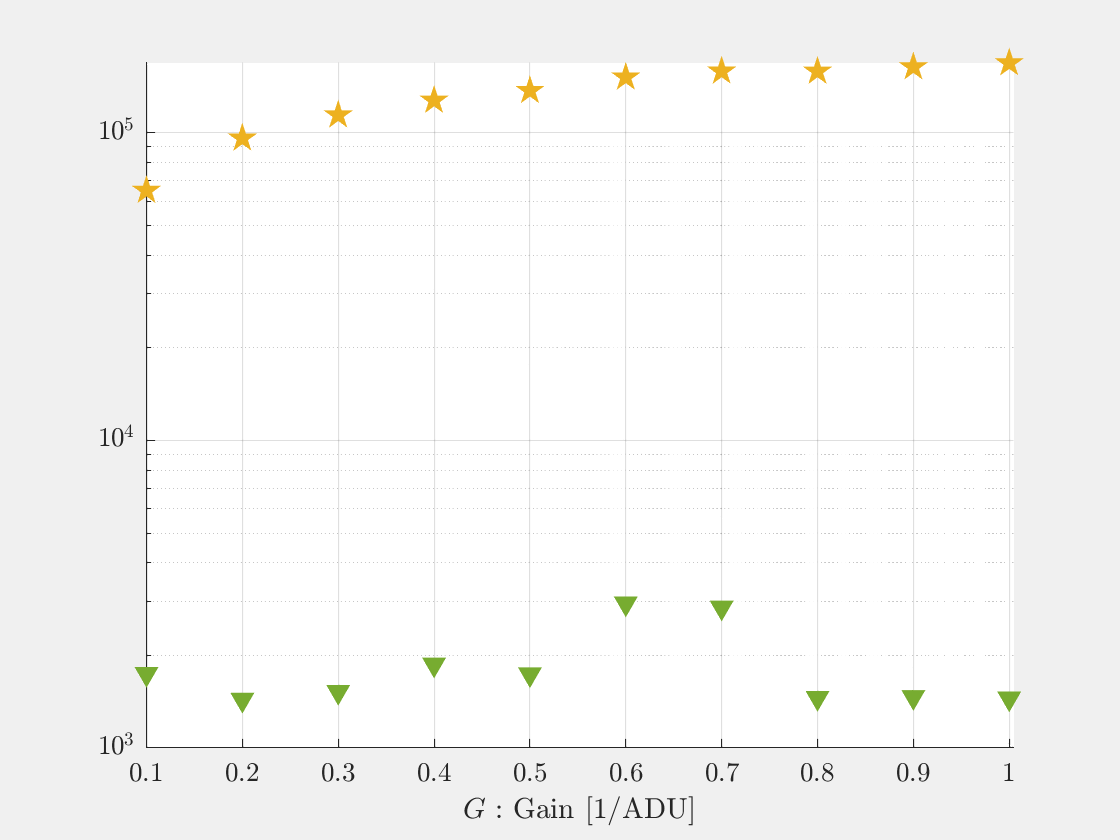

Figure = figure;    Axes = axes(Figure);    hold(Axes,  "on")
scatter(Axes, 1:10,abs(G.lnE), "Marker",'pentagram', "MarkerFaceColor",[0.929 0.694 0.125], "MarkerEdgeColor",[0.929 0.694 0.125], "SizeData", 100); 
scatter(Axes, 1:10,abs(G.lnM), "Marker",'V',         "MarkerFaceColor",[0.467 0.675 0.188],"MarkerEdgeColor",[0.467 0.675 0.188],  "SizeData",  50);    
grid on
yscale(Axes, "log");    hold(Axes, "off")
xticklabels(Axes, ["$0.{" + string([1,2,3,4,5,6,7,8,9]) + "}$","$1$"])
xlabel(Axes, "$G : $ Gain $[\mathrm{1/ADU}]$", "Interpreter",'LaTeX')
xlim(Axes, [0.995, 10.01])

xticklabels("$10^{" + string([1,2,3,4,5,6,7,8,9,10]) + "}$")

% save Data/ParametricG.mat Parametric

Reset
load Data/Inferred(ATTM).mat

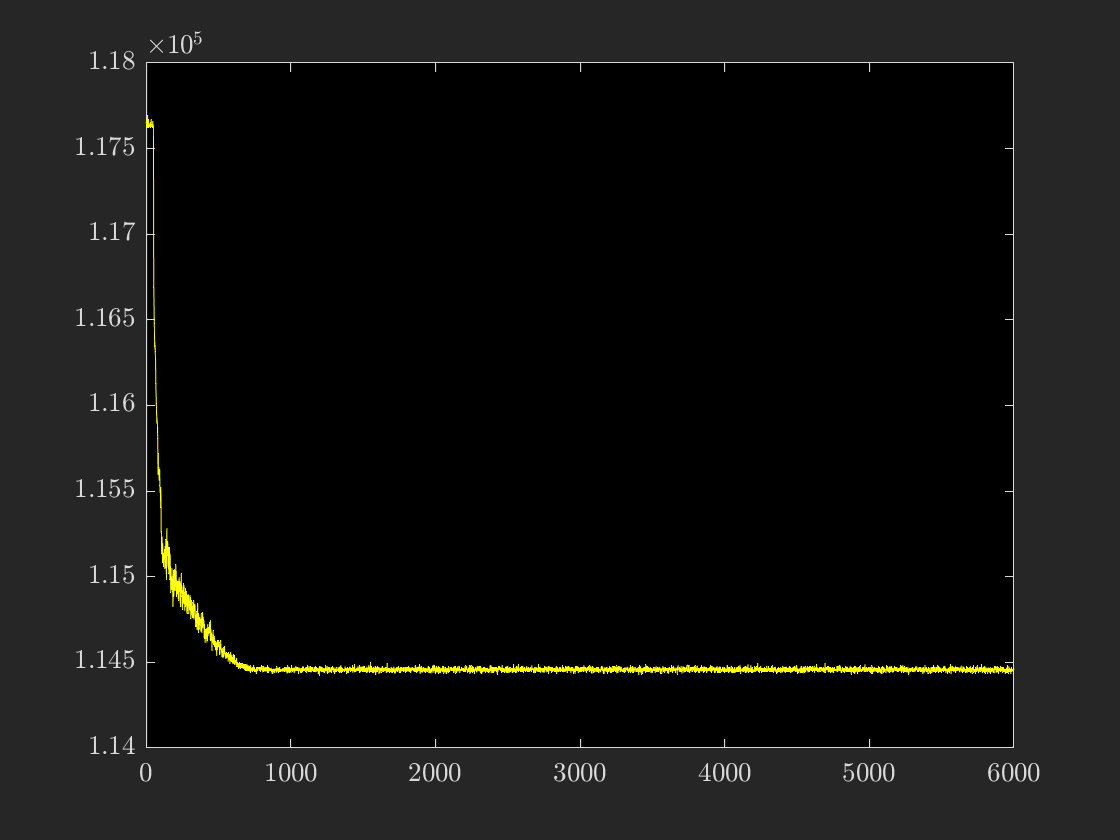

close all;    Figure = figure;    Axes = axes(Figure);    plot(Axes, abs(Chain.logEmission))
set(Figure,"Visible",'on')

plot(abs(Parametric.Fractal05.logPosterior))
yscale log

Models = "Directed" + ["F"  ;  "G"  ;  "H"] + ["0","1","2","3","4","5","6","7","8","9","10"];
for l = 1 : L
  Model = Models(l);

ans = 2×1 string array
    "F"
    "7"

  if isfile(Model)
    STRING = split(Model,"");
    MODEL = STRING(10 : end-1);
  Parametric.MODEL
  end
end